clc;clear;
losData = readmatrix("data\data_12_22.CSV");
losData(:,1) = smoothdata(losData(:,1));
losData(:,2) = smoothdata(losData(:,2));
lastDayNum = [366,732,1095,1460,1826,2191,2556,2921,3287,3652,4017]

lastDayNum =          366         732        1095        1460        1826        2191        2556        2921        3287        3652        4017


x=1:1:4017

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


T = zeros([10,370]);
U = zeros([10,370]);
R = zeros([10,370]);
oldi=0;
j=1

j = 1

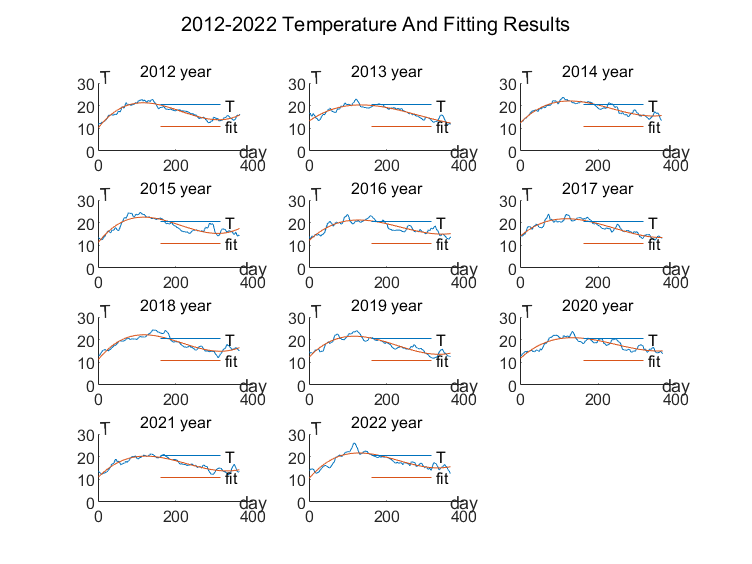

for i = lastDayNum
    t = losData(oldi+1:i,1)';
    t(1,370)=0;
    T(j,:) = t;

    u = losData(oldi+1:i,2)';
    u(1,370)=0;
    U(j,:) = u;

    r = losData(oldi+1:i,3)';
    r(1,370)=0;
    R(j,:) = r;

    j = j+1;
    oldi = i;
end

pT = zeros([10,4]);


oldi=0;
j=1;
figure
sgtitle("2012-2022 Temperature And Fitting Results",'fontsize',10)
for i = lastDayNum
    x=1:1:i-oldi;
    pT(j,1:4) = polyfit(x,T(j,1:i-oldi),3);
    Ty = polyval(pT(j,:),x);

    subplot(4,3,j);
    hold on
    title(mat2str(2011+j)+" year",'FontSize',8)
    plot(x,T(j,1:i-oldi));
    plot(x,Ty);
    ylim([0,30]);
    xlabel("day",'Position',[400,5]);
    ylabel("T",'Rotation',pi/2,'Position',[20,28]);
    legend("T","fit",'fontsize',8);
    legend("boxoff")
    hold off
   
    oldi = i;
    j=j+1;
end

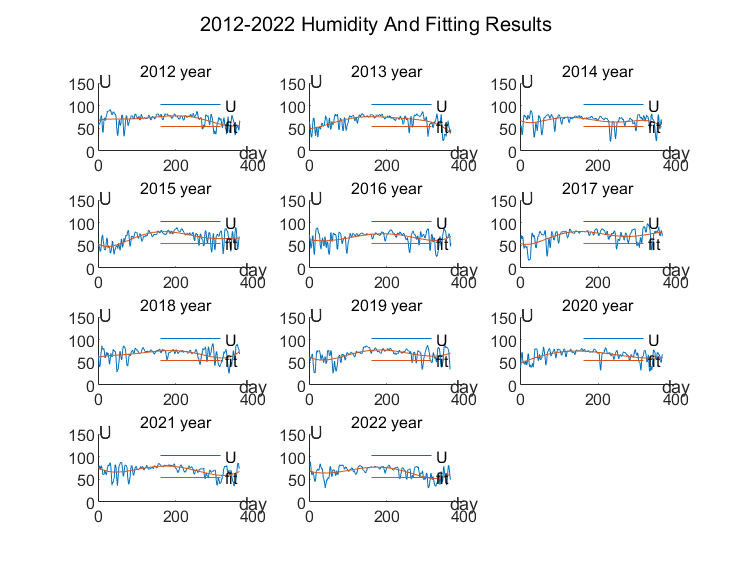

oldi=0;
j=1;
pU = zeros([10,6]);
figure
sgtitle("2012-2022 Humidity And Fitting Results",'fontsize',10)
for i = lastDayNum
    x=1:1:i-oldi;
    pU(j,1:6) = polyfit(x,U(j,1:i-oldi),5);
    Uy = polyval(pU(j,:),x);

    subplot(4,3,j);
    hold on
    title(mat2str(2011+j)+" year",'FontSize',8)
    plot(x,U(j,1:i-oldi));
    plot(x,Uy);
    ylim([0,150])
    xlabel("day",'Position',[400,22]);
    ylabel("U",'Rotation',pi/2,'Position',[20,130]);
    legend("U","fit",'fontsize',8);
    legend("boxoff")
    hold off
   
    oldi = i;
    j=j+1;
end

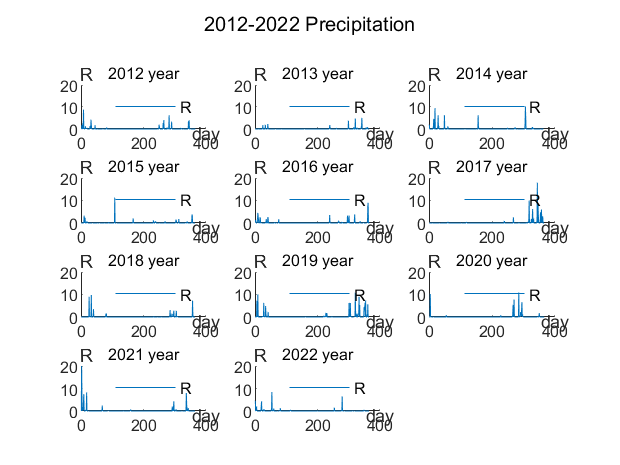


oldi=0;
j=1;
figure
sgtitle("2012-2022 Precipitation",'fontsize',10)
for i = lastDayNum
    x=1:1:i-oldi;

    subplot(4,3,j);
    hold on
    title(mat2str(2011+j)+" year",'FontSize',8)
    plot(x,R(j,1:i-oldi));
    ylim([0,20])
    xlabel("day",'Position',[400,3]);
    ylabel("R",'Rotation',pi/2,'Position',[20,20]);
    legend("R",'fontsize',8);
    legend("boxoff")
    hold off
   
    oldi = i;
    j=j+1;
end